% Now have a fixed structure
% TODO: Learn about TDL-C
% Now SCS is 60 kHz
% Doppler up to 2000

nTxAnts = 1; % 1 Tx antenna

carrier = nrCarrierConfig; % carrier waveform
init_pos_array = [2,3]

init_pos_array =      2     3


tic;
for init_pos_index=1:length(init_pos_array)

    init_pos_val = init_pos_array(init_pos_index);
    carrier.SubcarrierSpacing = 60; 
    
    pdsch = nrPDSCHConfig; % automatically set to QPSK
    pdsch.Modulation = "QPSK";
    pdsch.PRBSet = 0:carrier.NSizeGrid-1; % Full band allocation 
    
    % DMRS Config
    dmrs = nrPDSCHDMRSConfig;
    dmrs.DMRSTypeAPosition = init_pos_val;
    dmrs.DMRSAdditionalPosition = 0 
    
    dmrs.NumCDMGroupsWithoutData = 1; % 1 means all data
    % dmrs.NIDNSCID = 10; % not sure 
    dmrs.DMRSPortSet = 0;
    pdsch.DMRS = dmrs;
    
    [pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch); % each symbol represented by 2 bits, from QPSK
    
    source_bit_length = pdschInfo.G % Pretend the sequence is after source coding
    
    dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
    dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch); % locates the dmrs in the entire grid
    
    % this creates an empty resource grid
    Tx_pdschGrid_symbols = nrResourceGrid(carrier);
    [~,pdschAntIndices] = nrExtractResources(pdschIndices,Tx_pdschGrid_symbols);
    % fill in pdsch symbols to the indices of the RB that are reserved for PDSCH (non DMRS)
    
    % Add DMRS symbols
    Tx_pdschGrid_symbols(dmrsIndices) = dmrsSymbols
    

dmrs =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


source_bit_length = 16848

Tx_pdschGrid_symbols =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 + 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 + 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.

dmrs =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 3
     DMRSAdditionalPosition: 0
                 DMRSLength: 1
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


source_bit_length = 16848

Tx_pdschGrid_symbols =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.7071 - 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 - 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.

    avg_ber = 0;
    max_iter = 100;
    min_snr = 0;
    max_snr = 25; % rmb to change
    snr_vector = min_snr:1:max_snr;
    snr_vector_len = length(snr_vector);
    
    avg_ber_no_ce = zeros(snr_vector_len,1);
    avg_ber_with_ce = zeros(snr_vector_len,1); 
    total_biterr_with_ce_threshold = 100; % rmb to change
    
    
    
%     v = 30.0;                    % UE velocity in km/h
%     fc = 4e9;                    % carrier frequency in Hz
%     c = physconst('lightspeed'); % speed of light in m/s
    doppler_shift_vector = 0:10:2000;          % Range of Doppler frequencies to consider
    
    % Initialize BER matrix
    ber_matrix_with_ce = zeros(length(doppler_shift_vector), length(snr_vector));
    ber_matrix_no_ce = zeros(length(doppler_shift_vector), length(snr_vector));
    

    
    
    for doppler_shift_index = 1:length(doppler_shift_vector)
        doppler_shift_val = doppler_shift_vector(doppler_shift_index);
        
        tdl = nrTDLChannel;
        tdl.DelayProfile = 'TDL-C';
        tdl.DelaySpread = 300e-9;
        tdl.MaximumDopplerShift = doppler_shift_val;
        tdl.NumReceiveAntennas = 1;
    
        for snr_index=1:1:snr_vector_len
            snr_dB =  snr_vector(snr_index);
            total_biterr_no_ce = 0;
            total_biterr_with_ce = 0;
        
            for iter = 1:max_iter
        
                source_bits = randi([0, 1], source_bit_length, 1); % generate sequence
        
        %nrSymbolModulate(pdschBits, 'QPSK')
        %         
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %% MAPPING
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                % pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits) % from bits to symbols
        
                pdschSymbols = qammod(source_bits, 4, "gray", InputType='bit', UnitAveragePower=true);
                Tx_pdschGrid_symbols(pdschIndices) = pdschSymbols;
        
                % data Bits of grid
                %find the sequence bits
                Tx_pdschGrid_data_bits =  reshape(source_bits,[],1);
        
                Tx_pdschGrid_data_bits_length = numel(Tx_pdschGrid_data_bits);
                
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                % OFDM Modulation
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                % should the txwaveform have the same # as the rx
                % unsure about the dimensions of the waveform
                [Tx_waveform, waveformInfo] = nrOFDMModulate(carrier,Tx_pdschGrid_symbols);
            
                % Channel
                % Tapped Delay Line
                Rx_waveform = tdl(Tx_waveform);
                    
                % Add Noise
                Rxwaveform = awgn(Rx_waveform, snr_dB, 'measured');
                % Rxwaveform = Txwaveform;
        
                % OFDM Demodulation
                Rx_pdschGrid_symbols = nrOFDMDemodulate(carrier, Rxwaveform);
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                % Raw
                % Symbols to bits
                Rx_pdschGrid_raw_data_bits = qamdemod(Rx_pdschGrid_symbols(pdschIndices), 4, 'gray', OutputType='bit');
                Rx_pdschGrid_raw_data_bits = reshape(Rx_pdschGrid_raw_data_bits,[],1);
                ber_no_ce = biterr(Tx_pdschGrid_data_bits, Rx_pdschGrid_raw_data_bits);
        
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                % Can play around with this
                % Channel Estimation
                H = nrChannelEstimate(Rx_pdschGrid_symbols, dmrsIndices, dmrsSymbols);
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                
                % Perform equalization (X = Y / H)
                Rx_pdschGrid_symbols_with_ce = Rx_pdschGrid_symbols ./ H;
        
                % Remove pilot symbols
        %         Rx_pdschGrid_symbols_with_ce  = Rx_pdschGrid_symbols_with_ce(data)
            
                % Convert equalized data symbols back to bits
                Rx_pdschGrid_bits_with_ce = qamdemod(Rx_pdschGrid_symbols_with_ce(pdschIndices), 4, 'gray', 'OutputType', 'bit');
        
                % Calculate bit error with channel estimation and AWGN
                Rx_pdschGrid_bits_with_ce = reshape(Rx_pdschGrid_bits_with_ce, [], 1);
                biterr_with_ce = biterr(Tx_pdschGrid_data_bits, Rx_pdschGrid_bits_with_ce);        
        
                total_biterr_no_ce = total_biterr_no_ce + ber_no_ce;
                total_biterr_with_ce = total_biterr_with_ce + biterr_with_ce;
                
                if total_biterr_with_ce > total_biterr_with_ce_threshold 
                    break
                end
            end
            
            avg_ber_no_ce(snr_index) = total_biterr_no_ce / (iter* Tx_pdschGrid_data_bits_length);
            avg_ber_with_ce(snr_index) = total_biterr_with_ce / (iter* Tx_pdschGrid_data_bits_length);
            
            % Store BER
            ber_matrix_with_ce(doppler_shift_index, snr_index) = avg_ber_with_ce(snr_index); 
            ber_matrix_no_ce(doppler_shift_index, snr_index) = avg_ber_no_ce(snr_index);
        end
    end
    
    toc;

Elapsed time is 341.058969 seconds.


Elapsed time is 678.900952 seconds.


    avg_ber_no_ce

avg_ber_no_ce =     0.4983
    0.5030
    0.5042
    0.5015
    0.4989
    0.5085
    0.5097
    0.4887
    0.5015
    0.5200


avg_ber_no_ce =     0.5064
    0.4989
    0.5062
    0.5026
    0.4983
    0.5057
    0.5091
    0.4884
    0.5049
    0.5223


    avg_ber_with_ce

avg_ber_with_ce =     0.3602
    0.4001
    0.3043
    0.4355
    0.3070
    0.2838
    0.2618
    0.3146
    0.3835
    0.3730


avg_ber_with_ce =     0.3330
    0.3746
    0.2902
    0.4243
    0.2942
    0.2688
    0.2663
    0.3207
    0.3273
    0.3609


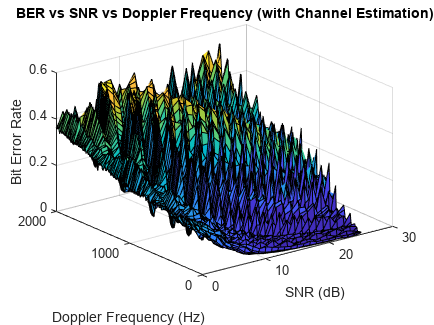

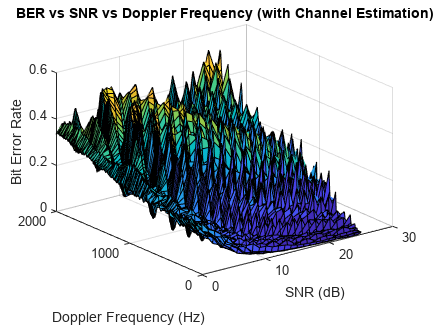


    % Define unique filename based on subcarrier spacing
    filename_prefix = sprintf("TYPEA_pos%d_single_length_no_additional_dmrs_scs60", init_pos_array(init_pos_index));

    % Plot 3D surface plot for BER with channel estimation
    figure;
    surf(snr_vector, doppler_shift_vector, (ber_matrix_with_ce));

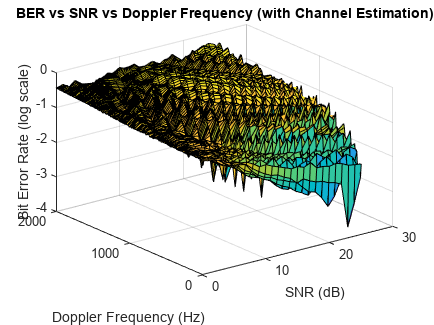

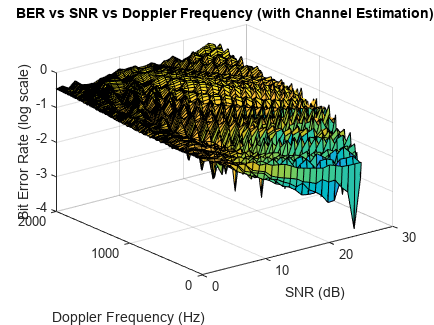

    xlabel('SNR (dB)');
    ylabel('Doppler Frequency (Hz)');
    zlabel('Bit Error Rate');
    title('BER vs SNR vs Doppler Frequency (with Channel Estimation)');
    savefig(filename_prefix + "with_ce_no_log.fig");

%     % Plot 3D surface plot for BER without channel estimation
%     figure;
%     surf(snr_vector, doppler_shift_vector, (ber_matrix_no_ce));
%     xlabel('SNR (dB)');
%     ylabel('Doppler Frequency (Hz)');
%     zlabel('Bit Error Rate');
%     title('BER vs SNR vs Doppler Frequency (without Channel Estimation)');
%     savefig(filename_prefix + "no_ce_no_log.fig");


    % LOG
    % Plot 3D surface plot for BER with channel estimation (log scale)
    figure;
    surf(snr_vector, doppler_shift_vector, log10(ber_matrix_with_ce));

    xlabel('SNR (dB)');
    ylabel('Doppler Frequency (Hz)');
    zlabel('Bit Error Rate (log scale)');
    title('BER vs SNR vs Doppler Frequency (with Channel Estimation)');
    savefig(filename_prefix + "with_ce_log.fig");

%     % LOG
%     % Plot 3D surface plot for BER without channel estimation (log scale)
%     figure;
%     surf(snr_vector, doppler_shift_vector, log10(ber_matrix_no_ce));
%     xlabel('SNR (dB)');
%     ylabel('Doppler Frequency (Hz)');
%     zlabel('Bit Error Rate (log scale)');
%     title('BER vs SNR vs Doppler Frequency (without Channel Estimation)');
%     savefig(filename_prefix + "no_ce_log.fig");
end    
    
    
    
    % figure;
    % semilogy(snr_vector, avg_ber_no_ce, 'b->');
    % hold on;
    % semilogy(snr_vector, avg_ber_with_ce, 'r-o');
    % 
    % xlabel('SNR (dB)');
    % ylabel('Bit Error Rate');
    % title('Bit Error Rate vs. SNR over AWGN');
    % legend('No CE', 'With CE');
    % grid on;
    %%

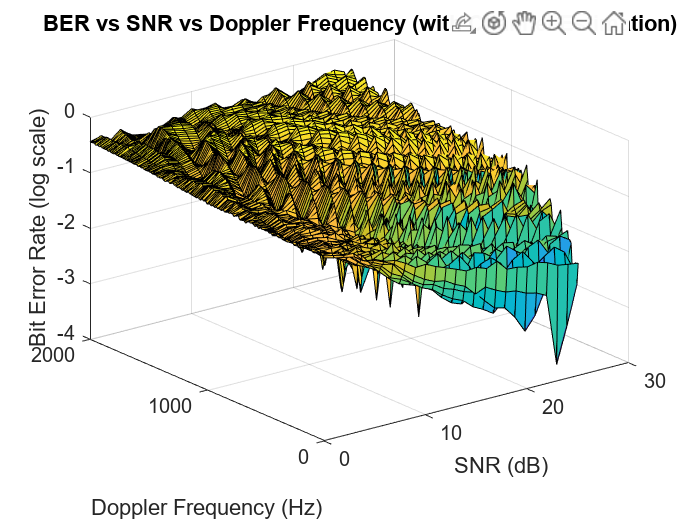

ans =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


openfig("TYPEA_pos2_single_length_no_additional_dmrs_scs60with_ce_log.fig")

% Specify the folder containing the saved figures
folderPath = 'C:\Users\user\OneDrive - University of Cambridge\Documents\MATLAB\TypeA_initpos_array'; % Replace 'path_to_folder' with the actual folder path

% List all files in the folder
files = dir(fullfile(folderPath, '*.fig'));

% Loop through each file
for i = 1:length(files)
    % Check if it's a figure file
    [~, ~, ext] = fileparts(files(i).name);
    if strcmpi(ext, '.fig')
        % Open the figure
        openfig(fullfile(folderPath, files(i).name));
    end
end